clear, clc, close all
data = csvread("PPG_9_calibration.csv",1);
fs = 100; % 100 samples per second
ts = 1/fs; % sample period  
% start_index = 4001;
% N = 3000; % N is the number of samples
% t = 0:ts:(N-1)*ts; % time axis
% Ir = (6.4/4096).*data(start_index:start_index+N-1,1); % change the magnitude to mA, IR
% Red = (6.4/4096).*data(start_index:start_index+N-1,2); % Red
Ir = (6.4/4096).*data(:,1);
% Ir = Ir(1500:2500,:);
Red = (6.4/4096).*data(:,2);
% Red = Red(1500:2500,:);
N = length(Ir);
t = 0:ts:(N-1)*ts; % time axis

beat_to_beat_interval = 1/2; % define heart rate = 0.5s
fp = 1.5/beat_to_beat_interval; % pass frequency is 3 Hz
fc = 5/beat_to_beat_interval; % stop frequecny is 10 Hz
rp = 0.1; % passband ripple at most 0.1 dB, this can be fixed
rs = 10; % stopband ripple at least 10 dB, this can be fixed
wp = fp/(fs/2); % passband width is 3 Hz, fs divided by 2 because of Nyquist's criterion
ws = fc/(fs/2); % stopband width is 15 Hz, i,e transmission band will be 3 to 15Hz
[n,Wn] = buttord(wp, ws, rp, rs) % design the buttord parameters

n = 3

Wn = 0.1411

[b,a] = butter(n,Wn,'low')

b =     0.0073    0.0219    0.0219    0.0073


a =     1.0000   -2.1201    1.5876   -0.4090


butter_data=filtfilt(b,a,Ir);

window_size_3 = floor(0.75*beat_to_beat_interval*fs); % 0.75*0.5*100 = 37.5
movemean_threshould = smoothdata(Ir,"movmean", window_size_3);

Let's try the new_peak_through function

[peaks,troughs] = new_peak_trough(butter_data);

plot them out

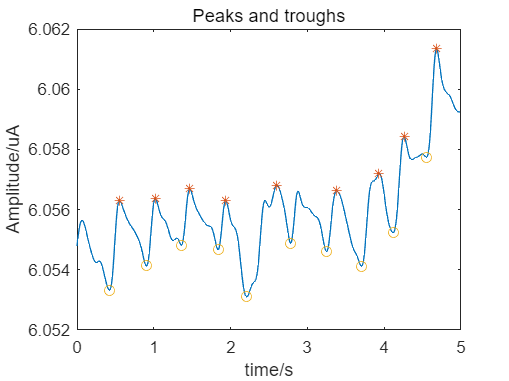

t_peaks = zeros(length(peaks),1);
peaks_value = zeros(length(peaks),1);
t_troughs = zeros(length(troughs),1);
troughs_value = zeros(length(troughs),1);
for i = 1:length(peaks) 
    t_peaks(i) = t(peaks(i));
    peaks_value(i) = butter_data(peaks(i));
end
for i = 1:length(troughs)
    t_troughs(i) = t(troughs(i));
    troughs_value(i) = butter_data(troughs(i));
end
close all;
figure
plot(t, butter_data);
hold on
plot(t_peaks,peaks_value,"*",t_troughs,troughs_value,"o");
title("Peaks and troughs")
xlabel("time/s")
ylabel("Amplitude/uA")

detect = artifact(peaks,troughs,t,butter_data);

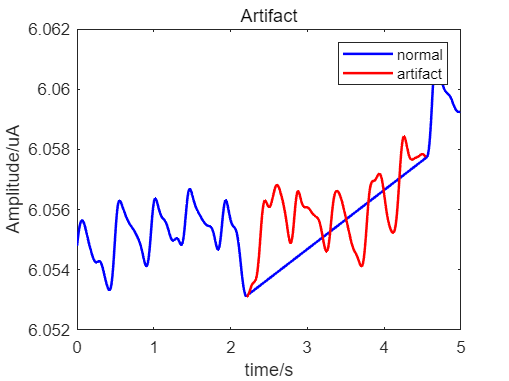

data_1 = find(detect == 0);
data_2 = find(detect ~= 0);
t_data_1 = zeros(length(data_1),1);
data_1_value = zeros(length(data_1),1);
t_data_2 = zeros(length(data_2),1);
data_2_value = zeros(length(data_2),1);
for i = 1:length(data_1) 
    t_data_1(i) = t(data_1(i));
    data_1_value(i) = butter_data(data_1(i));
end
for i = 1:length(data_2) 
    t_data_2(i) = t(data_2(i));
    data_2_value(i) = butter_data(data_2(i));
end
close all;
figure
plot(t_data_1, data_1_value,"b",t_data_2,data_2_value,"r","LineWidth",1.5);
legend("normal","artifact")
title("Artifact")
xlabel("time/s")
ylabel("Amplitude/uA")

画一下sampling rate

注意data1和data2需要自己从excel里面导入

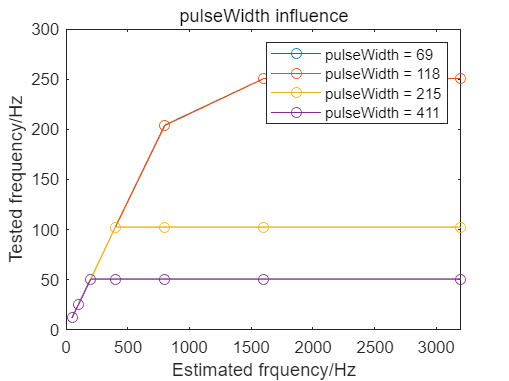

figure
sampleRate = [50, 100, 200, 400, 800, 1600, 3200];
for i = 1:4 
%     plot(sampleRate, data1(:,i), "*-");
    plot(sampleRate, data2(:,i), "o-");
    hold on
end
% legend(["sampleAverage = 1", "sampleAverage = 2", "sampleAverage = 4", "sampleAverage = 8"])
% title("SampleAverage influence")
legend(["pulseWidth = 69", "pulseWidth = 118", "pulseWidth = 215", "pulseWidth = 411"])
title("pulseWidth influence")
xlabel("Estimated frquency/Hz")
ylabel("Tested frequency/Hz")

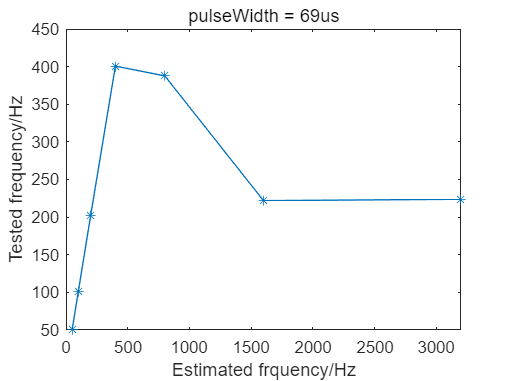

sampleRate = [50, 100, 200, 400, 800, 1600, 3200];
date = [50.67, 101.35, 202.53, 400.63, 387.73, 221.89, 223.75];
plot(sampleRate, date, "*-");
title("pulseWidth = 69us")
xlabel("Estimated frquency/Hz")
ylabel("Tested frequency/Hz")

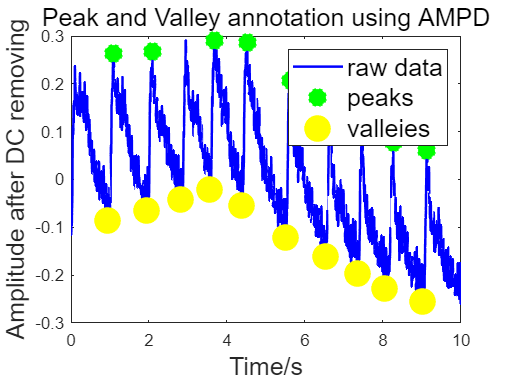

data = csvread("filtered_Data_filter_size_1_8000_10000.csv",1);
fs = 200; % 100 samples per second
ts = 1/fs; % sample period  
Green = (6.4/4096).*data(:,3);
Peaks = data(:,4);
Valleys = data(:,5);
N = length(Green);
t = 0:ts:(N-1)*ts; % time axis

t_peak = [];
t_val = [];
peak_value = [];
valley_value = [];
Peak_locs = find(Peaks);% find() find all the non-zero element's index
Valley_locs = find(Valleys);
for i = 1 : length(Peak_locs) 
    t_peak(end + 1) = t(Peak_locs(i));
    peak_value(end + 1) = Green(Peak_locs(i));
end
for i = 1 : length(Valley_locs)
    t_val(end + 1) = t(Valley_locs(i));
    valley_value(end + 1) = Green(Valley_locs(i));
end

close all
figure
plot(t,Green,'b',"LineWidth", 1.5);
hold on
plot(t_peak,peak_value,"g*",t_val,valley_value,"yo","LineWidth",10);
legend("raw data","peaks","valleies","FontSize", 15);
xlabel("Time/s","FontSize", 15);
ylabel("Amplitude after DC removing","FontSize", 15);
title("Peak and Valley annotation using AMPD","FontSize", 15);